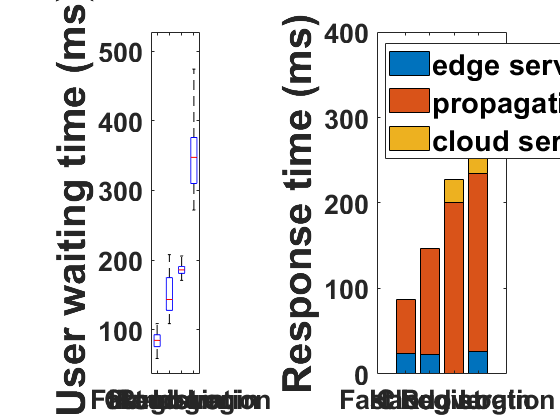

%cloud login
x1 = [186 173 191 205 187 190 180 207 187 185 190 157 182 181 205 184 205 185 211 185 178 200 185 178 184 176 185 211 171 181 210 186 179 187 179 186 199 182 223 186 198 185 206 178 181 184 187 190 186 189];
%fast login
x2 = [81 72 90 188 62 86 70 65 84 85 64 83 59 86 76 89 77 97 63 89 80 88 63 93 69 89 134 84 92 96 125 95 76 101 78 85 78 98 60 88 103 95 109 87 85 84 95 88 74 85];
%handover
x3 = [125 203 142 124 139 157 120 144 144 133 170 136 139 149 125 140 135 109 117 148 119 128 150 138 144 175 143 201 200 144 132 182 157 205 180 150 205 179 205 148 182 205 123 208 125 125 120 125 136 135];
%registration
x4 = [377 300 362 505 372 342 305 504 294 371 348 355 288 474 320 310 292 313 308 329 272 309 291 311 313 488 420 466 380 352 376 362 353 347 469 333 454 407 468 320 336 358 371 351 350 303 304 318 291 341];
figure
subplot(1,2,1);
boxplot([x2' x3' x1' x4'], 'Symbol', '');
set(gca, 'XTickLabel',{'Fast Login', 'Handover', 'Cloud Login', 'Registration'},'FontSize',20, 'FontWeight',"bold");
ylabel('User waiting time (ms)','FontSize',30);
%xlabel('');
title('','FontSize',30);
x5 = [23.86 63 0; 22.7 124.66 0; 0 200.72 26.62; 26.28 207.98 123.4];
subplot(1,2,2);
bar(x5, 'stack');
set(gca, 'XTickLabel',{'Fast Login', 'Handover', 'Cloud Login', 'Registration'},'FontSize', 20, 'FontWeight',"bold");
title('','FontSize',30);
ylabel('Response time (ms)','FontSize',30, 'FontWeight',"bold");
legend('edge server processing time','propagation delay','cloud server processing time','FontSize', 22,'Location','northwest');

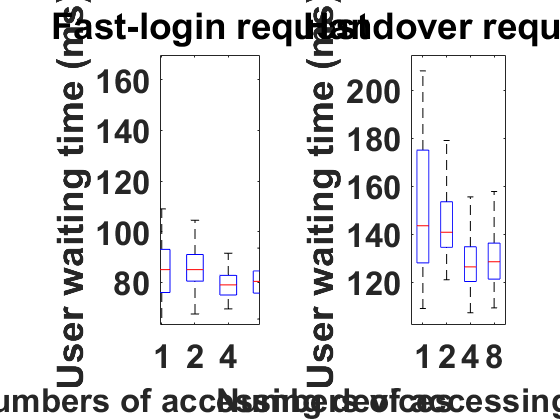

figure
% 1 device fast login
x6 = [81 72 90 188 62 86 70 65 84 85 64 83 59 86 76 89 77 97 63 89 80 88 63 93 69 89 134 84 92 96 125 95 76 101 78 85 78 98 60 88 103 95 109 87 85 84 95 88 74 85];
% 2 device fast login
x7 = [91.5 71.5 98.5 109 77.5 81 82.5 70.5 114 91.5 67.5 88 93 75.5 92.5 87 75 86 90 75.5 83 85 104.5 80.5 86 103 85 83 98 82 91 89.5 77 68.5 84 90.5 80 120.5 83 85 91 85.5 86 81 83 79.5 85.5 80 84 89.5];
% 4 device fast login
x8 = [63.25 81 74.75 72.5 80.25 82.75 99 73.5 78.5 79.25 86.25 83.75 74.5 82.75 78.25 80.25 81.25 73.75 81.5 78 70.5 91.5 79.75 81.75 86.25 77 105.5 77.5 84.25 82 70.75 86 76.5 73 76.75 69.5 78.75 77.25 75.75 77.25 86 84 75.25 82 74 81.5 75 87 71.75 81.25];
% 8 device fast login
x15 = [65.5 82.25 75.125 70.5 82.5 85.75 99.5 75.5 81.25 81.5 88.25 85.5 75.75 84.5 80.25 82.5 82.75 75.5 83.5 79.5 72.5 93.5 81.25 80.5 87.5 79.5 107.25 78.5 86.5 83 69.75 88.5 76.125 74 75.75 70.5 77.75 77.25 75.125 78.5 86.5 85 76.25 81.5 79 79.5 74 86.5 75.75 83.75];
subplot(1,2,1);
boxplot([x6' x7' x8' x15'], 'Symbol', '');
%title('User waiting time for fast login step with different number of devices access simultaniously','FontSize',12);
set(gca, 'XTickLabel',{'1', '2', '4', '8'}, 'FontSize', 25, 'FontWeight',"bold");
ylabel('User waiting time (ms)','FontSize',28, 'FontWeight',"bold");
xlabel('Numbers of accessing devices','FontSize',25, 'FontWeight',"bold");
title('Fast-login request', 'FontSize',27);



% 1 device handover
x9 = [125 203 142 124 139 157 120 144 144 133 170 136 139 149 125 140 135 109 117 148 119 128 150 138 144 175 143 201 200 144 132 182 157 205 180 150 205 179 205 148 182 205 123 208 125 125 120 125 136 135];
% 2 device handover
x10 = [126 122.5 130 130 146 158.5 139 130 206 139.5 151.5 148.5 137 150 138 121 147.5 152.5 209.5 135.5 126.5 141 129 137 205 201 201.5 201.5 126 145.5 153.5 126 139 202.5 152.5 151 185 139.5 135 170.5 127 157.5 140 150.5 179 138 140.5 142.5 132 134.5];
% 4 device handover
x11 = [134.75 118.75 136.75 122.25 122.75 120.5 129.25 120.25 146.5 120 107.25 141 121.5 130.75 133.25 120.25 111.25 120.5 133 119.5 127.25 112 118.75 122.5 134.25 149.75 135.5 124.5 203.5 107.5 132.75 137.75 125.5 155.5 120.5 133.25 137.5 140.75 118.75 115.5 147 127.25 129 120 124 132.5 151 120.5 128 112.75];
% 8 device handover
x12 = [136.25 121.75 138.5 121.125 122.5 125.5 128.5 118.125 149.5 121.125 117.25 136.5 121.25 128.75 131.25 123.75 113.25 121.25 134.5 120 129.125 113.75 120 124.25 135.5 151.5 137.25 126.5 205.5 109.25 134.75 138.25 127.25 157.75 122.25 135 140.25 140.75 119.75 117.25 147.25 129.75 131 123.5 123.5 134.5 137.5 128.5 128.5 120.5];
subplot(1,2,2);
boxplot([x9' x10' x11' x12'], 'Symbol', '');
title('Handover request', 'FontSize',27);
set(gca, 'XTickLabel',{'1', '2', '4', '8'}, 'FontSize', 25, 'FontWeight',"bold");
ylabel('User waiting time (ms)','FontSize',28, 'FontWeight',"bold");
xlabel('Numbers of accessing devices','FontSize',25, 'FontWeight',"bold");

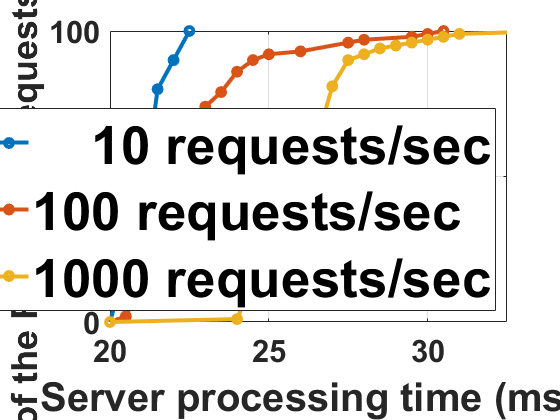

figure
x18 = [20,22, 23, 24, 25];
x19 = [0, 40, 80, 90, 100];
plot(x18,x19, '-o', 'LineWidth', 3);hold on;

x13 = [20, 21, 22, 23, 24, 25, 26, 27, 28, 29, 30, 32, 35, 36, 39, 470, 41];
x14 = [0, 2, 14, 35, 51, 68, 74, 79, 86, 90, 92, 93, 96, 97, 98, 99, 100];

plot(x13,x14, '-o', 'LineWidth', 3);hold on;
x16 = [20, 28, 29, 30, 31, 32, 33, 34, 35, 36, 37, 38, 39, 40, 41, 42, 48, 52];
x17 = [0, 1, 14, 29, 44, 54, 62, 81, 90, 92, 94, 95, 96, 97, 98, 99, 100, 100];
%set(gca,'FontSize',20);
plot(x16,x17, '-o', 'LineWidth', 3);hold on;
grid on;
xlim([20 45]);
set(gca, 'FontWeight',"bold");
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',23,'FontWeight','bold')
l = legend('10 requests/sec','  100 requests/sec','1000 requests/sec','FontSize', 16);
set(legend,'FontSize',40);
legend('Location',"southeast");
ylabel('Proportion of the Fast-login requests processed (%)','FontSize',27,'FontWeight',"bold");
xlabel('Server processing time (ms)','FontSize',30,'FontWeight',"bold");
title('','FontSize',21,'FontWeight',"bold");

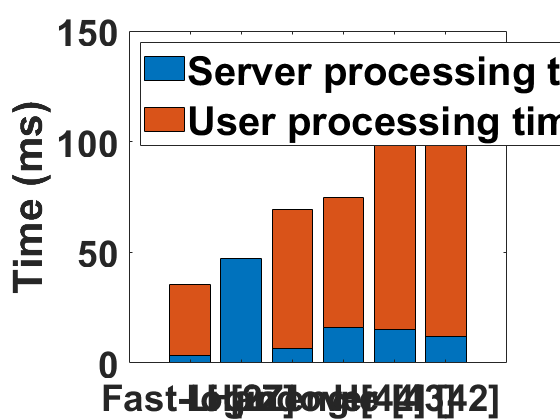

figure
x23 = [3.4876 32.086; 47.009 0; 6.6962 62.777; 15.843 58.733;15.206 83.449; 11.913 128.868];
bar(x23,'stack');
%set(gca, 'XTickLabel',{'User', 'Server'}, 'FontSize', 30,'FontWeight',"bold");
ylabel('Time (ms)','FontSize',30,'FontWeight',"bold");
set(gca, 'XTickLabel',{'Fast-login', 'Li [27]', 'Handover', 'Zeng [44]', 'He [43]', 'Li [42]'},'FontSize', 28, 'FontWeight',"bold");
legend('Server processing time', 'User processing time','Location','northwest','FontSize', 30);
title('','FontSize', 30);

figure
fl = [1 2 3 4 5 6 7 8 9 10];
fl_int = [0 0 0 0 0 34.6 67.3 83.67 91.83 95.913];
ho_int = [0 0 0 0 0 31.02 65.51 82.754 91.37 95.69];
dr_int = [0 0 0 0 0 0 22.4 61.2 80.6 90.3]

dr_int =          0         0         0         0         0         0   22.4000   61.2000   80.6000   90.3000


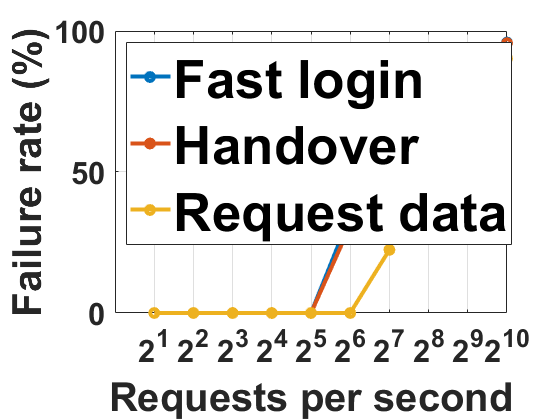

plot(fl,fl_int, '-o', 'LineWidth', 3);hold on;
plot(fl,ho_int, '-o', 'LineWidth', 3);hold on;
plot(fl,dr_int, '-o', 'LineWidth', 3);hold on;grid on;
set(gca, 'FontWeight',"bold");
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',23,'FontWeight','bold')
xticks([1 2 3 4 5 6 7 8 9 10]);
l = legend('Fast login','Handover','Request data');
set(legend,'FontSize',40);
legend('Location',"northwest");
xlabel('Requests per second','FontSize',30,'FontWeight',"bold");
ylabel('Failure rate (%)','FontSize',30,'FontWeight',"bold");
set(gca, 'XTickLabel',{'2^1', '2^2', '2^3', '2^4', '2^5', '2^6', '2^7', '2^8', '2^9', '2^{10}'});